# Rotations about a point different than the origin

The rotation matrix $Q=\left\lbrack \begin{array}{cc}
\mathrm{cos}\theta  & -\mathrm{sin}\theta \\
\mathrm{sin}\theta  & \mathrm{cos}\theta 
\end{array}\right\rbrack$ performs a rotation about the origin, but what if we want to rotate about a point $P=\left(P_x ,P_y \right)$ different than the origin? To accomplish this we need to 

- translate the object so that $P$ will coincide with the origin, i.e. translate $-P_x \;$units horizontally and $-P_y$ units vertically

- rotate the object

- translate the object back, i.e. translate $P_x$ units horizontally and $P_y$ units vertically

To compose the three transformations above, we multiply the appropriate matrices:


$$\left\lbrack \begin{array}{ccc}
1 & 0 & P_x \\
0 & 1 & P_y \\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
\mathrm{cos}\theta  & -\mathrm{sin}\theta  & 0\\
\mathrm{sin}\theta  & \mathrm{cos}\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & -P_x \\
0 & 1 & -P_y \\
0 & 0 & 1
\end{array}\right\rbrack$$


Note that the rotation matrix is written in homogeneous coordinates.

# Example 9

In this example, we first translate the square horizontally $8$ units using increments of $0\ldotp 2$. We then rotate the resulting square clockwise $\frac{\pi }{2}$ radians around the vertex $\left(9,0\right)$ using increments of $\frac{\pi }{6}$ radians.

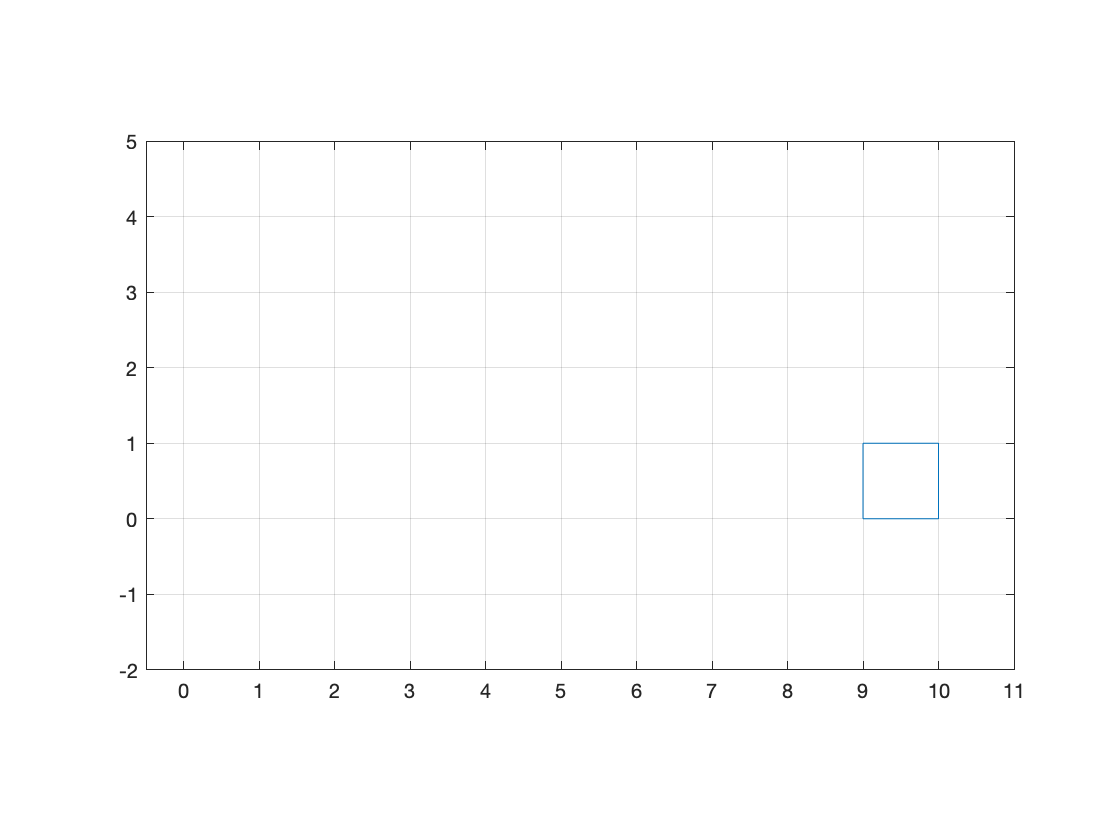

clf
S=[0,1,1,0,0;0,0,1,1,0;1,1,1,1,1]; % square in homogeneous coordinates
M1 = [1,0,0.2;0,1,0;0,0,1]; % first translation matrix
theta = pi /6; % define the angle theta
Q=[cos(theta),-sin(theta),0;sin(theta),cos(theta),0;0 ,0 ,1]; %rotation matrix about (0,0)
QP =[1 ,0 ,9;0 ,1 ,0;0 ,0 ,1]*Q'*[1,0,-9;0,1,0;0,0,1]; % rotation matrix about (9,0)
p = plot(S(1,:),S(2,:)); % plot the original square
axis equal, axis([-0.5,11,-2,5]), grid on
for i = 1:40
   S = M1*S; % compute the translated square
   set(p,'xdata',S(1,:),'ydata',S(2,:)); % plot the translated square
   pause(0.2)
end
for i = 1:3
  S=QP*S; % compute the rotated square
  set(p,'xdata',S(1,:),'ydata',S(2,:)); % plot the rotated square
  pause(0.2)
end